# Calibration du Modele Heston


% On clean les donnes
df = ZCNCALLSDATA;
valuation_date = datetime(2026,4,2);   % date As-of de Bloomberg
S0 = 44.29; % pris a partir de PX_LAST

target_maturity = 11.53;   % in months
tolerance = 0.1;            % in months

df.Ticker = string(df.Ticker);

%% Le prochain extrait la data a maturite, Ticker et type

n = height(df);

Ticker_clean = strings(n,1);
Expiry_date  = NaT(n,1);
Code_option  = strings(n,1);

for i = 1:n
    tk = strtrim(df.Ticker(i));

    if strlength(tk) == 0 || ismissing(tk)
        continue
    end

    parts = split(tk);

    if numel(parts) >= 3
        Ticker_clean(i) = parts(1);

        try
            Expiry_date(i) = datetime(parts(2), 'InputFormat', 'MM/dd/yy');
        catch
            Expiry_date(i) = NaT;
        end

        Code_option(i) = parts(3);
    end
end

df.Ticker = Ticker_clean;
df.Expiry_date = Expiry_date;
df.Code_option = Code_option;

%% Date A maturite
days_to_maturity = days(df.Expiry_date - valuation_date);
df.Maturity_months = days_to_maturity / 365.0 * 12;
df.T_years = df.Maturity_months / 12;

numCols = ["Strike","Bid","Ask"];

for c = numCols
    if ~isnumeric(df.(c))
        df.(c) = str2double(string(df.(c)));
    end
end

%% mid-price
df.Mid = (df.Bid + df.Ask) / 2;
df = df(abs(df.Maturity_months - target_maturity) <= tolerance, :);

%% On laisse les Strike centres
df = df(df.Strike >= 0.8*S0 & df.Strike <= 1.2*S0, :);
df = sortrows(df, "Strike");

prix = flipud(ZCNDAILY.PX_LAST); %prix historique
dates = flipud(ZCNDAILY.Date);
y = diff(log(prix));   % rendements de ZCN

% Calcul des statistiques
n = length(y);                              
mean_daily = mean(y);                       
std_daily = std(y);                        

mean_annualized = mean_daily * 252;
std_annualized = std_daily * sqrt(252);

% Statistiques de forme
skewness_val = skewness(y);                 % Asymétrie
excess_kurtosis = kurtosis(y) - 3;          % Excès de kurtosis (normal = 0)

min_daily = min(y);
max_daily = max(y);

statistiques = table([n; mean_annualized; std_annualized; skewness_val; ...
                      excess_kurtosis; min_daily; max_daily], ...
                     'VariableNames', {'Valeur'}, ...
                     'RowNames', {'Nombre d''observations'; 'Moyenne annualisée'; ...
                                  'Écart-type annualisé'; 'Asymétrie (skewness)'; ...
                                  'Excès de kurtosis'; 'Minimum journalier'; 'Maximum journalier'})

statistiques = 7×1 table
                              Valeur  
                             _________

    Nombre d'observations         1255
    Moyenne annualisée         0.11078
    Écart-type annualisé       0.13096
    Asymétrie (skewness)        -0.358
    Excès de kurtosis           3.4186
    Minimum journalier       -0.047501
    Maximum journalier        0.053385


La moyenne annualisée estimée à partir des rendements journaliers est de l'ordre de 11%, ce qui est cohérent avec les performances récentes des marchés actions nord-américains, notamment dans un contexte de forte croissance des valeurs technologiques.

Cependant, cette estimation reste dépendante de la fenêtre d'observation et peut être biaisée par des conditions de marché favorables. Elle est donc interprétée comme une approximation empirique du drift sous P.

Mdl = gjr(1,1);
EstMdl = estimate(Mdl,y)

 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value       StandardError    TStatistic      PValue   
                   __________    _____________    __________    ___________

    Constant       4.2971e-06     1.1455e-06         3.7511      0.00017607
    GARCH{1}          0.82831       0.022666         36.544     2.2024e-292
    ARCH{1}             2e-12       0.017021      1.175e-10               1
    Leverage{1}         0.223       0.033247         6.7074      1.9813e-11



EstMdl =   gjr with properties:

     Description: "GJR(1,1) Conditional Variance Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 1
               Q: 1
        Constant: 4.29705e-06
           GARCH: {0.828313} at lag [1]
            ARCH: {2e-12} at lag [1]
        Leverage: {0.223003} at lag [1]
          Offset: 0

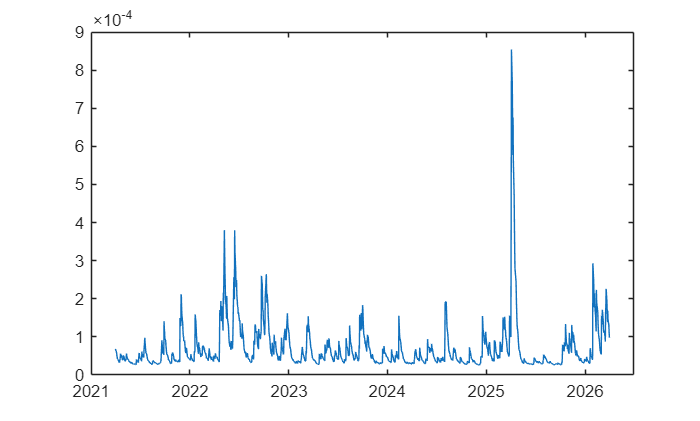

V_historic = infer(EstMdl,y);  % calcul de la variance historique, en fonction du modèle estimé
plot(dates(1:end-1),V_historic)

v0 = V_historic(end)*252 % annualisé la variance pour Heston

v0 = 0.0247

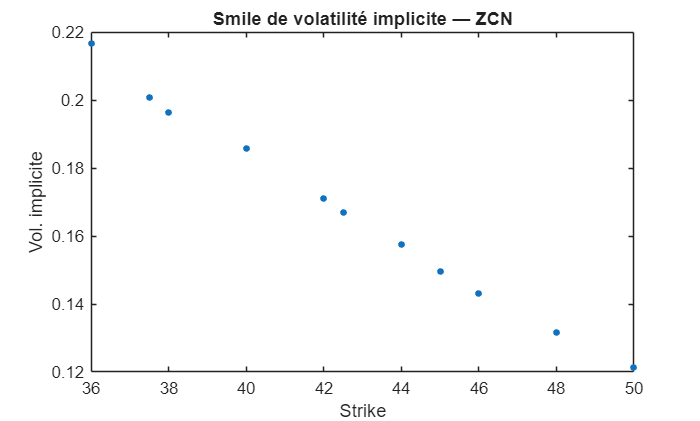

r  = 0.0253 ;    % taux sans risque (CORRA OIS approximé) -> voire le document Vasicek_Whole pour la Methodologie
q  = 0.02143814;  % rendement de dividende équivalent (parité put-call approximée)

strikes   = df.Strike;
midprices = df.Mid;
T         = df.T_years(1);    % maturité unique (toutes les lignes ont la même)


vol_impl = blsimpv(S0, strikes, r, T, midprices, 'Yield', q, 'Class', 'call');

figure;
plot(strikes, vol_impl, '.', 'MarkerSize', 12);
xlabel('Strike'); ylabel('Vol. implicite');
title('Smile de volatilité implicite — ZCN');

vol_impl_moy = nanmean(vol_impl);

valuation_date = datetime(2026, 4, 2);
Maturite       = valuation_date + days(round(T * 365));

Call_HESTON = @(ThetaV, Kappa, SigmaV, RhoSV) ...
    max(1e-8, optByHestonNI(r, S0, valuation_date, Maturite, 'call', ...
                            strikes, v0, ThetaV, Kappa, SigmaV, RhoSV, ...
                            'DividendYield', q));

%% Volatilités implicites du modèle Heston
vol_impl_HESTON = @(ThetaV0, Kappa0, SigmaV0, RhoSV0) ...
    arrayfun(@(K, C) blsimpv(S0, K, r, T, C, 'Yield', q, 'Class', 'call'), ...
             strikes, Call_HESTON(ThetaV0, Kappa0, SigmaV0, RhoSV0));


MSE_impv = @(params) local_MSE_IV( ...
    vol_impl, ...
    vol_impl_HESTON(params(1), params(2), params(3), params(4)));

% initialisation
ThetaV_depart = nanmean(V_historic * 252);
Kappa_depart  = 10;
SigmaV_depart = 0.25;
RhoSV_depart  = -0.6;

% notre interval de valeur
lb = [0.005, 0.1, 0.05, -0.95];
ub = [0.15,  12, 5, -0.1];

options = optimset('Display','iter');

[param_opt, fval_opt] = fmincon(MSE_impv, ...
    [ThetaV_depart, Kappa_depart, SigmaV_depart, RhoSV_depart], ...
    [], [], [], [], lb, ub, [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.465537e-03    0.000e+00    1.129e-01
    1      10    8.366409e-04    0.000e+00    9.542e-02    6.013e-03
    2      15    5.936392e-04    0.000e+00    3.147e-02    1.377e-02
    3      20    6.250746e-04    0.000e+00    4.964e-03    1.307e-02
    4      25    6.875143e-04    0.000e+00    2.634e-02    2.632e-02
    5      30    7.701256e-04    0.000e+00    4.684e-02    5.504e-02
    6      35    8.478948e-04    0.000e+00    6.573e-02    1.265e-01
    7      40    7.915937e-04    0.000e+00    7.336e-02    2.894e-01
    8      45    4.110675e-04    0.000e+00    4.698e-02    6.257e-01
    9      50    8.661221e-05    0.000e+00    8.104e-03    1.104e+00
   10      55    8.946730e-05    0.000e+00    5.380e-03    8.384e-02
   11      60    9.923991e-05    0.000e+00    1.833e-03    8.999e-02
   12      65    1.168399e-04    0.000e+00    8

function J = local_MSE_IV(vol_mkt, vol_mod)

    idx = ~isnan(vol_mkt) & ~isnan(vol_mod) & isfinite(vol_mkt) & isfinite(vol_mod);

    if sum(idx) == 0
        J = 1e10;
        return
    end

    err = vol_mkt(idx) - vol_mod(idx);
    J = mean(err.^2);

end

fprintf('  theta  (var long terme)  : %.6f  (vol long terme : %.4f)\n', param_opt(1), sqrt(param_opt(1)));

  theta  (var long terme)  : 0.033274  (vol long terme : 0.1824)


fprintf('  kappa  (vitesse retour)  : %.4f\n',  param_opt(2));

  kappa  (vitesse retour)  : 9.7668


fprintf('  xi     (vol-of-vol)      : %.4f\n',  param_opt(3));

  xi     (vol-of-vol)      : 1.9214


fprintf('  rho    (corrélation)     : %.4f\n',  param_opt(4));

  rho    (corrélation)     : -0.7461


fprintf('  v0     (var initiale)    : %.6f  (vol initiale : %.4f)\n', v0, sqrt(v0));

  v0     (var initiale)    : 0.024668  (vol initiale : 0.1571)


fprintf('  Condition Feller 2κθ≥ξ² : %.6f >= %.6f  → %s\n', ...
    2*param_opt(2)*param_opt(1), param_opt(3)^2, ...
    string(2*param_opt(2)*param_opt(1) >= param_opt(3)^2));

  Condition Feller 2κθ≥ξ² : 0.649967 >= 3.691871  → false


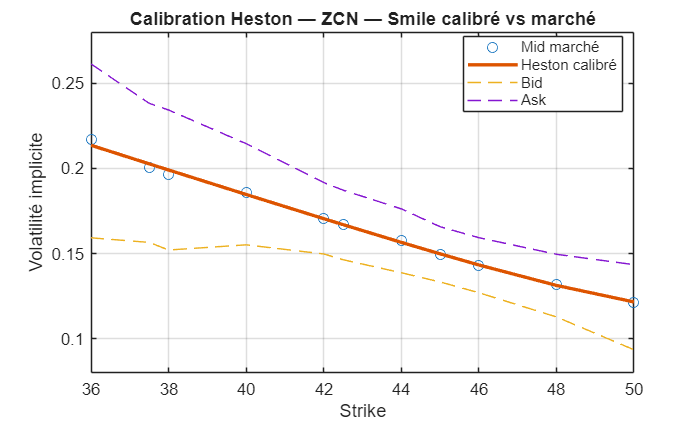


%% même que le cours
vol_impl_calibre = vol_impl_HESTON(param_opt(1), param_opt(2), param_opt(3), param_opt(4));


vol_bid = blsimpv(S0, strikes, r, T, df.Bid, 'Yield', q, 'Class', 'call');
vol_ask = blsimpv(S0, strikes, r, T, df.Ask, 'Yield', q, 'Class', 'call');

figure;
plot(strikes, vol_impl,       'o',  'DisplayName', 'Mid marché');     hold on;
plot(strikes, vol_impl_calibre, '-', 'LineWidth', 2, 'DisplayName', 'Heston calibré');
plot(strikes, vol_bid,         '--', 'DisplayName', 'Bid');
plot(strikes, vol_ask,         '--', 'DisplayName', 'Ask');
hold off;
legend('Location', 'best');
xlabel('Strike'); ylabel('Volatilité implicite');
title('Calibration Heston — ZCN — Smile calibré vs marché');
grid on;

## Passage a la Mesure $\mathbb{P}
$

% Methode 1ere faite : Quasi MLE (qui donne des quasi-estime)


vP_series = V_historic(:) * 252;
dates_vP  = dates(2:end);

idx_valid = ~isnan(vP_series) & isfinite(vP_series) & (vP_series > 0);
vP_series = vP_series(idx_valid);
dates_vP  = dates_vP(idx_valid);

% Transitions observees
v_t   = vP_series(1:end-1);
v_tp1 = vP_series(2:end);

dtP = 1/252;%pas

theta_Q = param_opt(1);
kappa_Q = param_opt(2);
xi_Q    = param_opt(3);
rho_Q   = param_opt(4);

% Hypothese rho normalement se conserve
rho_P = rho_Q;


% Initialisation et bornes
thetaP_init = mean(vP_series, 'omitnan');
kappaP_init = 2.0;
xiP_init    = 0.5;

x0P = [thetaP_init, kappaP_init, xiP_init];
lbP = [1e-5, 1e-4, 1e-4];
ubP = [1.0,  50.0, 10.0];

optionsP = optimset('Display','iter', ...
                    'TolX',1e-8, ...
                    'TolFun',1e-8, ...
                    'MaxIter',1000, ...
                    'MaxFunEvals',10000);

% Quasi log-vraisemblance negative
QMLE_obj = @(x) local_negloglik_CIR_Gaussian(v_t, v_tp1, dtP, x(1), x(2), x(3));

[paramP_opt, negloglikP] = fmincon(QMLE_obj, x0P, ...
    [], [], [], [], lbP, ubP, [], optionsP);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4   -4.660850e+03    0.000e+00    2.251e+03
    1      13   -4.754658e+03    0.000e+00    2.482e+02    3.868e-01
    2      18   -4.760084e+03    0.000e+00    2.409e+02    1.307e-01
    3      22   -4.800694e+03    0.000e+00    2.143e+02    1.437e+00
    4      26   -4.801586e+03    0.000e+00    8.846e+02    1.206e+00
    5      32   -4.807067e+03    0.000e+00    7.004e+02    7.172e-01
    6      36   -4.808432e+03    0.000e+00    9.095e+01    2.738e+00
    7      40   -4.823408e+03    0.000e+00    1.090e+02    1.032e+00
    8      44   -4.825184e+03    0.000e+00    5.632e+01    1.222e+00
    9      48   -4.825701e+03    0.000e+00    2.752e+01    3.146e-01
   10      52   -4.826413e+03    0.000e+00    4.876e+01    1.385e+00
   11      56   -4.826688e+03    0.000e+00    2.051e+02    1.629e+00
   12      60   -4.827691e+03    0.000e+00    6


theta_P = paramP_opt(1);
kappa_P = paramP_opt(2);
xi_P    = paramP_opt(3);

%  Moments conditionnels sous le modele estime


m_cond_P = theta_P + (v_t - theta_P) * exp(-kappa_P * dtP);

var_cond_P = xi_P^2 * ( ...
    v_t .* exp(-kappa_P * dtP) .* (1 - exp(-kappa_P * dtP)) / kappa_P ...
    + theta_P * (1 - exp(-kappa_P * dtP)).^2 / (2 * kappa_P) );

var_cond_P = max(var_cond_P, 1e-12);
resid_P    = v_tp1 - m_cond_P;
std_resid_P = resid_P ./ sqrt(var_cond_P);


%  Prime de risque de volatilite implicite


lambda_v = (kappa_Q - kappa_P) / xi_Q;
theta_Q_implied = (kappa_P * theta_P) / kappa_Q;

fprintf('  theta^P                 : %.6f  (vol LT sous P : %.4f)\n', theta_P, sqrt(theta_P));

  theta^P                 : 0.017870  (vol LT sous P : 0.1337)


fprintf('  kappa^P                 : %.6f\n', kappa_P);

  kappa^P                 : 14.957208


fprintf('  xi^P                    : %.6f\n', xi_P);

  xi^P                    : 0.699345


fprintf('  rho^P                   : %.6f\n', rho_P);

  rho^P                   : -0.746108


theta_Q

theta_Q = 0.0333

 kappa_Q

kappa_Q = 9.7668

xi_Q

xi_Q = 1.9214

lambda_v

lambda_v = -2.7013

theta_Q_implied

theta_Q_implied = 0.0274

fprintf('  Feller sous P : 2*kappa^P*theta^P = %.6f,  xi_P^2 = %.6f  -> %s\n', ...
    2*kappa_P*theta_P, xi_P^2, string(2*kappa_P*theta_P >= xi_P^2));

  Feller sous P : 2*kappa^P*theta^P = 0.534572,  xi_P^2 = 0.489083  -> true


fprintf('  Feller sous Q : 2*kappa^Q*theta^Q = %.6f,  xi_Q^2 = %.6f  -> %s\n', ...
    2*kappa_Q*theta_Q, xi_Q^2, string(2*kappa_Q*theta_Q >= xi_Q^2));

  Feller sous Q : 2*kappa^Q*theta^Q = 0.649967,  xi_Q^2 = 3.691871  -> false


rmse_cirP = sqrt(mean(resid_P.^2, 'omitnan'));
mae_cirP  = mean(abs(resid_P), 'omitnan');


fprintf('  Negative log-likelihood : %.6f\n', negloglikP);

  Negative log-likelihood : -4829.029684


fprintf('  RMSE conditionnel       : %.6f\n', rmse_cirP);

  RMSE conditionnel       : 0.006665


fprintf('  MAE conditionnel        : %.6f\n', mae_cirP);

  MAE conditionnel        : 0.002851


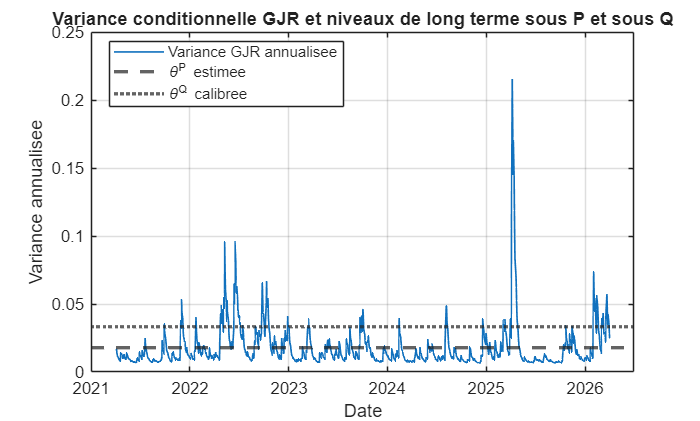

figure;
plot(dates_vP, vP_series, 'LineWidth', 1); hold on;
yline(theta_P, '--', 'LineWidth', 2);
yline(theta_Q, ':',  'LineWidth', 2);
hold off;
xlabel('Date');
ylabel('Variance annualisee');
title('Variance conditionnelle GJR et niveaux de long terme sous P et sous Q');
legend('Variance GJR annualisee', '\theta^P estimee', '\theta^Q calibree', ...
       'Location', 'best');
grid on;

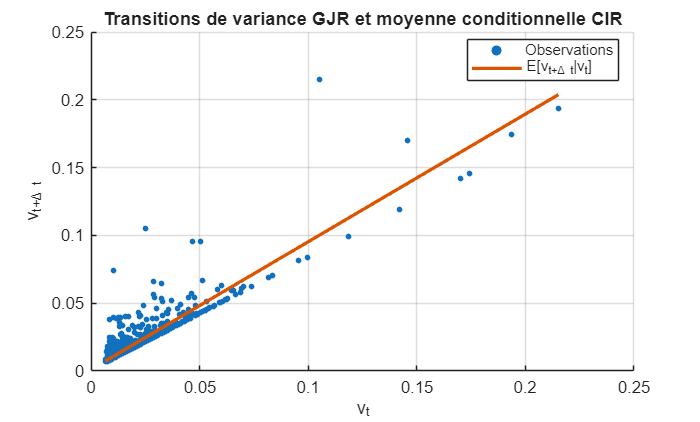

figure;
scatter(v_t, v_tp1, 12, 'filled'); hold on;
v_grid = linspace(min(v_t), max(v_t), 200)';
m_grid = theta_P + (v_grid - theta_P) * exp(-kappa_P * dtP);
plot(v_grid, m_grid, 'LineWidth', 2);
hold off;
xlabel('v_t');
ylabel('v_{t+\Delta t}');
title('Transitions de variance GJR et moyenne conditionnelle CIR');
legend('Observations', 'E[v_{t+\Delta t}|v_t]', 'Location', 'best');
grid on;

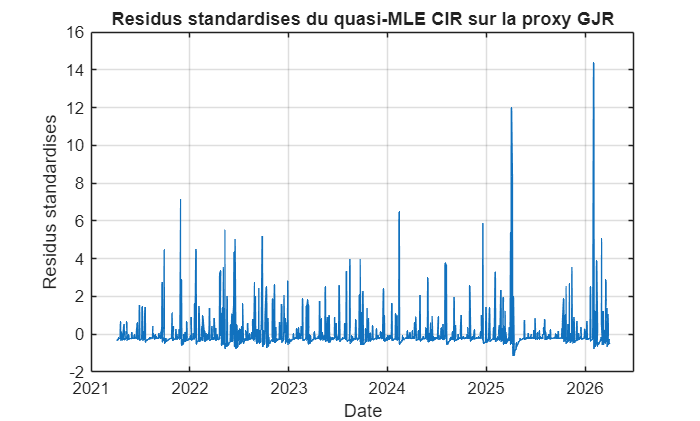

figure;
plot(dates_vP(2:end), std_resid_P, 'LineWidth', 1);
xlabel('Date');
ylabel('Residus standardises');
title('Residus standardises du quasi-MLE CIR sur la proxy GJR');
grid on;

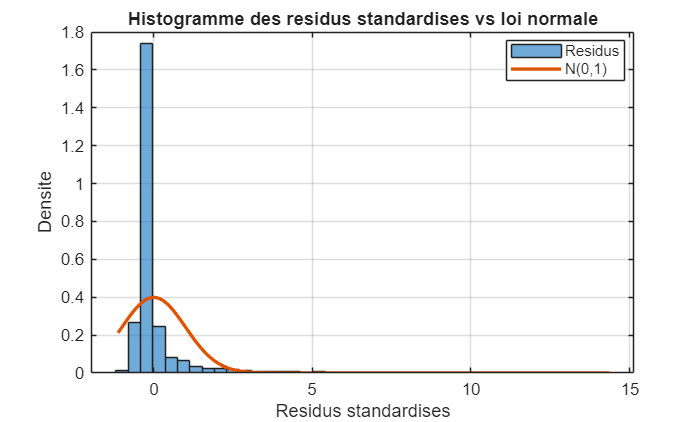

figure;

histogram(std_resid_P, 40, 'Normalization', 'pdf'); hold on;

x = linspace(min(std_resid_P), max(std_resid_P), 200);
plot(x, normpdf(x,0,1), 'LineWidth', 2);

hold off;
xlabel('Residus standardises');
ylabel('Densite');
title('Histogramme des residus standardises vs loi normale');
legend('Residus', 'N(0,1)', 'Location', 'best');
grid on;


function nll = local_negloglik_CIR_Gaussian(v_t, v_tp1, dt, theta, kappa, xi)

    if theta <= 0 || kappa <= 0 || xi <= 0 || ...
       ~isfinite(theta) || ~isfinite(kappa) || ~isfinite(xi)
        nll = 1e12;
        return
    end

    expk = exp(-kappa * dt);

    m = theta + (v_t - theta) * expk;

    s2 = xi^2 * ( ...
        v_t .* expk .* (1 - expk) / kappa ...
        + theta * (1 - expk)^2 / (2 * kappa) );

    if any(~isfinite(m)) || any(~isfinite(s2))
        nll = 1e12;
        return
    end

    s2 = max(s2, 1e-12);

    loglik_vec = -0.5 * ( log(2*pi*s2) + ((v_tp1 - m).^2) ./ s2 );

    if any(~isfinite(loglik_vec))
        nll = 1e12;
        return
    end

    nll = -sum(loglik_vec);

    if ~isfinite(nll)
        nll = 1e12;
    end
end

## Methode MLE EXACTE

Utilisant le fait que CIR Heston suit une distribution chi-square non centrale law

vP_series = V_historic(:) * 252;
dates_vP  = dates(2:end);

idx_valid = ~isnan(vP_series) & isfinite(vP_series) & (vP_series > 0);
vP_series = vP_series(idx_valid);
dates_vP  = dates_vP(idx_valid);

% transitions
v_t   = vP_series(1:end-1);
v_tp1 = vP_series(2:end);

dtP = 1/252;

theta_Q = param_opt(1);
kappa_Q = param_opt(2);
xi_Q    = param_opt(3);
rho_Q   = param_opt(4);

rho_P = rho_Q; % hypothese standard


thetaP_init = mean(vP_series, 'omitnan');
kappaP_init = 2.0;
xiP_init    = 0.5;

x0P = [thetaP_init, kappaP_init, xiP_init];

lbP = [1e-6, 1e-4, 1e-4];
ubP = [2.0, 50, 5.0];

optionsP = optimset('Display','iter', ...
                    'TolX',1e-8, ...
                    'TolFun',1e-8, ...
                    'MaxIter',1000, ...
                    'MaxFunEvals',20000);

QMLE_obj = @(x) local_negloglik_CIR_exact(v_t, v_tp1, dtP, x(1), x(2), x(3));

[paramP_opt, negloglikP] = fmincon(QMLE_obj, x0P, ...
    [], [], [], [], lbP, ubP, [], optionsP);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4   -5.130182e+03    0.000e+00    3.714e+02
    1      16   -5.133136e+03    0.000e+00    3.774e+02    4.815e-02
    2      21   -5.133872e+03    0.000e+00    3.679e+02    5.588e-03
    3      29   -5.137060e+03    0.000e+00    3.558e+02    9.330e-02
    4      34   -5.148373e+03    0.000e+00    1.072e+02    8.300e-01
    5      39   -5.149367e+03    0.000e+00    1.777e+02    5.805e-01
    6      43   -5.150145e+03    0.000e+00    4.243e+01    6.013e-02
    7      47   -5.150636e+03    0.000e+00    1.947e+01    2.134e-01
    8      51   -5.152549e+03    0.000e+00    2.650e+02    1.403e+00
    9      55   -5.154477e+03    0.000e+00    1.824e+02    6.849e-01
   10      60   -5.158550e+03    0.000e+00    5.831e+02    2.965e+00
   11      64   -5.168633e+03    0.000e+00    1.076e+03    7.546e+00
   12      70   -5.173256e+03    0.000e+00    6


theta_P = paramP_opt(1);
kappa_P = paramP_opt(2);
xi_P    = paramP_opt(3);

% Moment conditionnelles

expk = exp(-kappa_P * dtP);

m_cond_P = theta_P + (v_t - theta_P) * expk;

var_cond_P = xi_P^2 * ( ...
    v_t .* expk .* (1 - expk) / kappa_P ...
    + theta_P * (1 - expk)^2 / (2 * kappa_P) );

var_cond_P = max(var_cond_P, 1e-12);

resid_P     = v_tp1 - m_cond_P;
std_resid_P = resid_P ./ sqrt(var_cond_P);

lambda_v = (kappa_Q - kappa_P) / xi_Q;
theta_Q_implied = (kappa_P * theta_P) / kappa_Q;


fprintf('  theta^P : %.6f  (vol LT : %.4f)\n', theta_P, sqrt(theta_P));

  theta^P : 0.017771  (vol LT : 0.1333)


fprintf('  kappa^P : %.6f\n', kappa_P);

  kappa^P : 27.900162


fprintf('  xi^P    : %.6f\n', xi_P);

  xi^P    : 0.550470


fprintf('  rho^P   : %.6f\n', rho_P);

  rho^P   : -0.746108


fprintf('  theta^Q         : %.6f\n', theta_Q);

  theta^Q         : 0.033274


fprintf('  kappa^Q         : %.6f\n', kappa_Q);

  kappa^Q         : 9.766785


fprintf('  xi^Q            : %.6f\n', xi_Q);

  xi^Q            : 1.921424


fprintf('  lambda_v        : %.6f\n', lambda_v);

  lambda_v        : -9.437466


fprintf('  theta^Q implied : %.6f\n', theta_Q_implied);

  theta^Q implied : 0.050765


fprintf('  P: 2*kappa*theta = %.6f vs xi^2 = %.6f -> %s\n', ...
    2*kappa_P*theta_P, xi_P^2, string(2*kappa_P*theta_P >= xi_P^2));

  P: 2*kappa*theta = 0.991621 vs xi^2 = 0.303017 -> true



fprintf('  Q: 2*kappa*theta = %.6f vs xi^2 = %.6f -> %s\n', ...
    2*kappa_Q*theta_Q, xi_Q^2, string(2*kappa_Q*theta_Q >= xi_Q^2));

  Q: 2*kappa*theta = 0.649967 vs xi^2 = 3.691871 -> false



rmse_cirP = sqrt(mean(resid_P.^2, 'omitnan'));
mae_cirP  = mean(abs(resid_P), 'omitnan');

fprintf('  NegLogLik : %.6f\n', negloglikP);

  NegLogLik : -5175.841879


fprintf('  RMSE      : %.6f\n', rmse_cirP);

  RMSE      : 0.006665


fprintf('  MAE       : %.6f\n', mae_cirP);

  MAE       : 0.002857


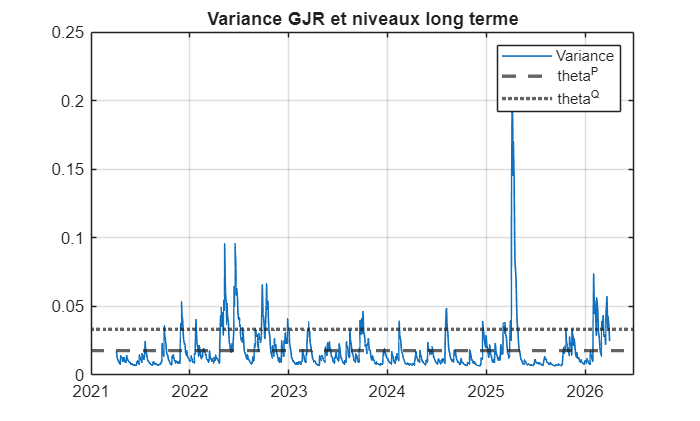

figure;
plot(dates_vP, vP_series, 'LineWidth', 1); hold on;
yline(theta_P, '--', 'LineWidth', 2);
yline(theta_Q, ':',  'LineWidth', 2);
hold off;
title('Variance GJR et niveaux long terme');
legend('Variance','theta^P','theta^Q'); grid on;

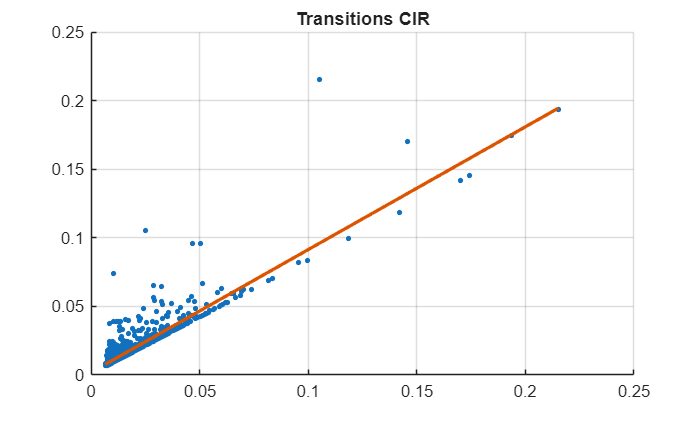


figure;
scatter(v_t, v_tp1, 10, 'filled'); hold on;
v_grid = linspace(min(v_t), max(v_t), 200)';
m_grid = theta_P + (v_grid - theta_P) * exp(-kappa_P * dtP);
plot(v_grid, m_grid, 'LineWidth', 2);
hold off;
title('Transitions CIR'); grid on;

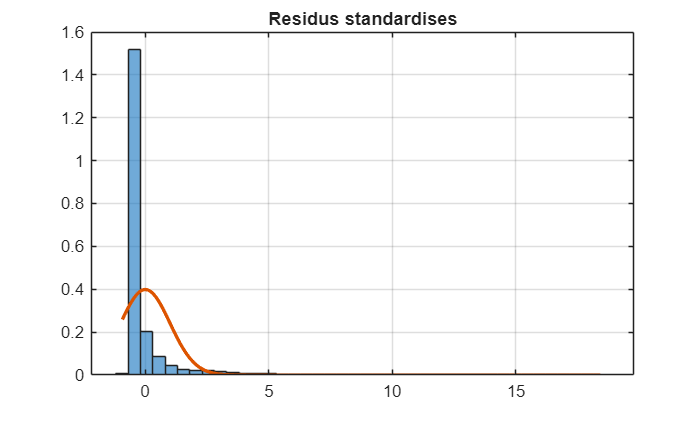


figure;
histogram(std_resid_P, 40, 'Normalization', 'pdf'); hold on;
x = linspace(min(std_resid_P), max(std_resid_P), 200);
plot(x, normpdf(x,0,1), 'LineWidth', 2);
hold off;
title('Residus standardises'); grid on;

function nll = local_negloglik_CIR_exact(v_t, v_tp1, dt, theta, kappa, xi)

    if theta <= 0 || kappa <= 0 || xi <= 0 || ...
       ~isfinite(theta) || ~isfinite(kappa) || ~isfinite(xi)
        nll = 1e12;
        return
    end

    expk = exp(-kappa * dt);

    c = (xi^2 * (1 - expk)) / (4 * kappa);
    d = 4 * kappa * theta / xi^2;

    lambda = (4 * kappa * expk ./ (xi^2 * (1 - expk))) .* v_t;

    x = v_tp1 ./ c;

    % sécurité numérique (troncation)
    x = max(x, 1e-12);

    pdf_vals = ncx2pdf(x, d, lambda);

    % éviter log(0)
    pdf_vals(pdf_vals < 1e-300) = 1e-300;

    loglik = log(pdf_vals) - log(c);

    if any(~isfinite(loglik))
        nll = 1e12;
        return
    end

    nll = -sum(loglik);

    if ~isfinite(nll)
        nll = 1e12;
    end

end

